#     Frequency Devision Multiplexing - FDM

## Variables :

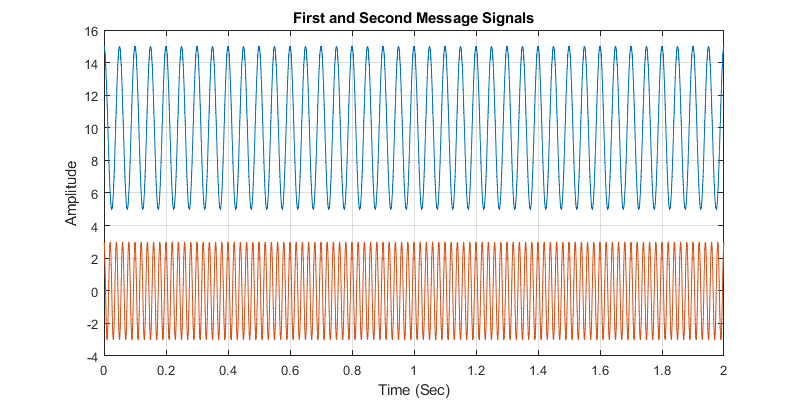

% Samples
fs =5000;
endpoint=2;
t=[0:1/fs:endpoint];

%frequency scale
l=length(t);
kd=[-l/2:1:(l/2)-1];

%Signal Parameters
fc1=100;
fm1=20;
fc2=300;
fm2=50;
Vc1=12;
Vc2=10;
Vm1=5;
Vm2=3;

% Signals in time domain
vm1=Vm1*cos(2*pi*fm1*t);
vm2=Vm2*cos(2*pi*fm2*t);
f1=figure;
plot(t,vm1+10);hold on % blue
plot(t,vm2); % orange
title("First and Second Message Signals");
xlabel('Time (Sec)');
ylabel('Amplitude');
set(f1,'Position',[0 0 800 400]);
grid on;


% Carrier siganls
vc1=Vc1*cos(2*pi*fc1*t);
vc2=Vc2*cos(2*pi*fc2*t);


## Modulated Signals :

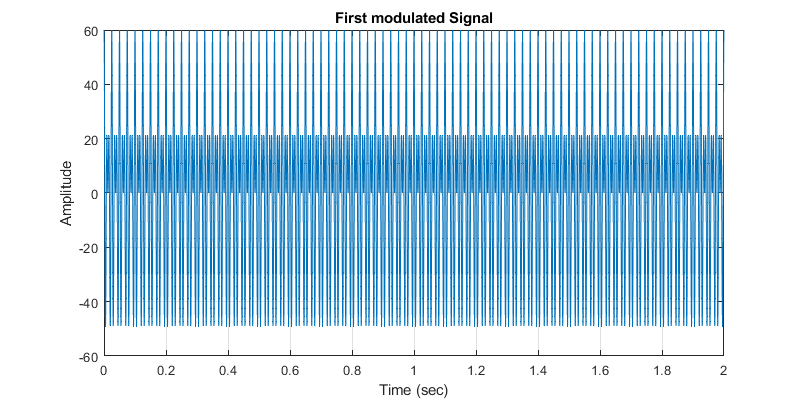


vam1=vm1.*vc1; % Components : fc1-fm1, fc1+fm1
f2=figure;
plot(t,vam1);
title("First modulated Signal");
xlabel('Time (sec)');
ylabel('Amplitude');
set(f2,'Position',[0 0 800 400]);
grid on;

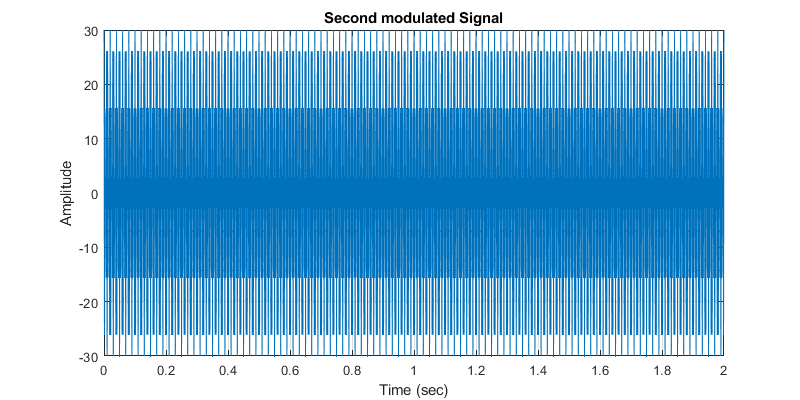

% xlim([0.000 0.200])
% ylim([-59 60])

vam2=vm2.*vc2; % Components : fc2-fm2, fc2+fm2
plot(t,vam2);
title("Second modulated Signal");
xlabel('Time (sec)');
ylabel('Amplitude');
set(f2,'Position',[0 0 800 400]);
grid on;

% xlim([0.000 0.200])
% ylim([-35 35])

## FDM signal :

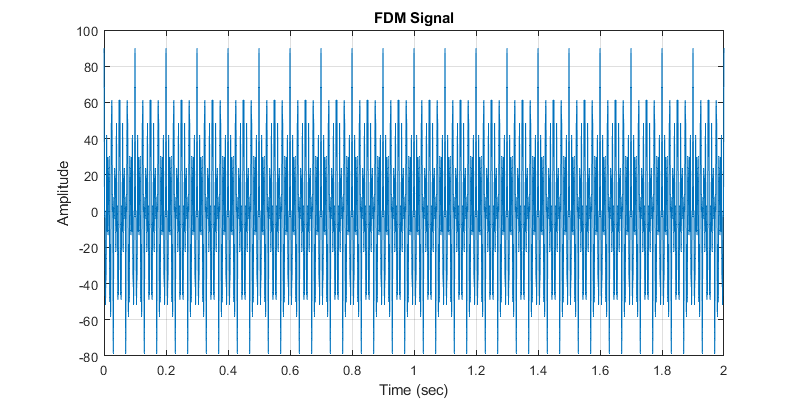

f3=figure;
vfdm= vam1+vam2;
plot(t,vfdm);
title("FDM Signal");
xlabel('Time (sec)');
ylabel('Amplitude');
set(f3,'Position',[0 0 800 400]);
grid on;

% xlim([0.000 0.200])
% ylim([-100 100])

##                              Receiving End

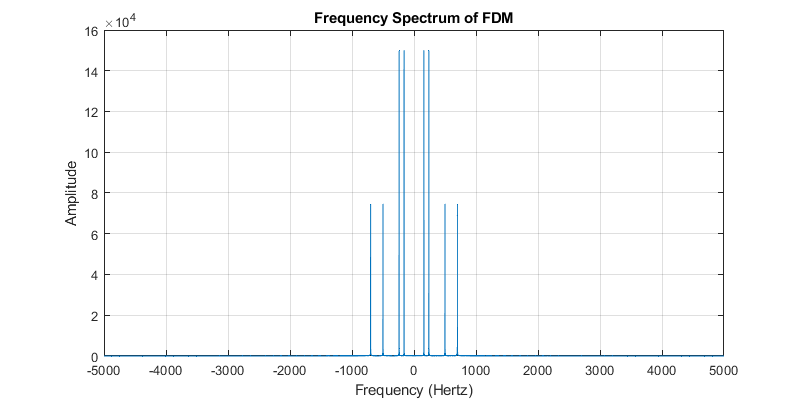

%frequency spectrum of fdm
vfdmf=abs(fftshift(fft(vfdm))); %Components : fc1-fm1, fc2-fm2, fc1+fm1, fc2+fm2
f4=figure;
% subplot(2,1,1);
plot(kd,vfdmf);
title("Frequency Spectrum of FDM");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f4,'Position',[0 0 800 400]);
grid on;

## Band Pass Filters :

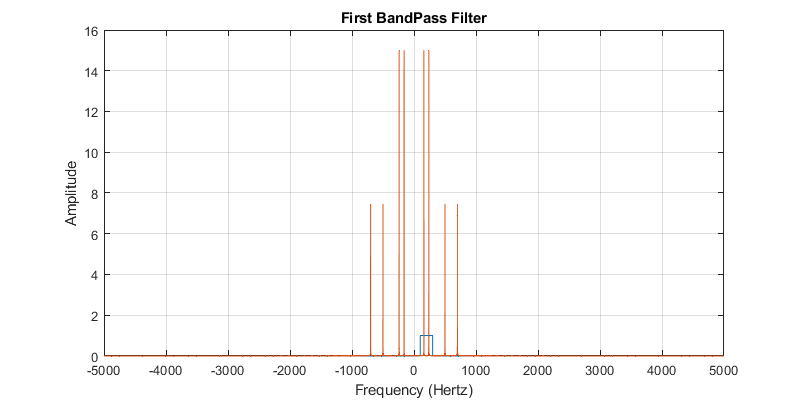

%                    Filter for First Signal
tuner1=80;
a=round(l/2);
% b=round(fc1-fm1-tuner1);
bpf1=[zeros(1,a+2*fc1-fm1-tuner1),ones(1,2*fm1+2*tuner1),zeros(1,l-(a+(2*fc1-fm1)+2*fm1+tuner1))];
% bpf1=[zeros(1,a+b),ones(1,2*fm1+2*tuner1),zeros(1,l-(a+b+2*fm1+2*tuner1))];
f5=figure;
plot(kd,bpf1);hold on
plot(kd,vfdmf/10000);
title("First BandPass Filter");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f5,'Position',[0 0 800 400]);
grid on;

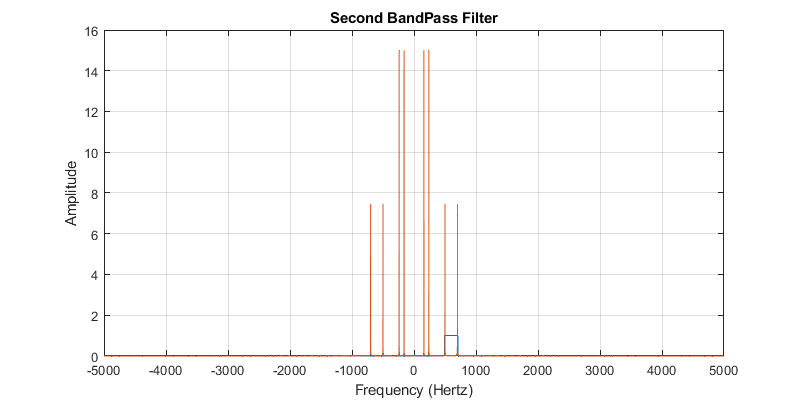


%First BandPass Filter Output
vamf1= vfdmf.*bpf1;

%                     Filter for Second Signal
tuner2=80;
bpf2=[zeros(1,a+2*fc2-fm2-tuner2),ones(1,2*fm2+2*tuner2),zeros(1,l-(a+(2*fc2-fm2)+2*fm2+tuner2))];
f6=figure;
plot(kd,bpf2);hold on
plot(kd,vfdmf/10000);
title("Second BandPass Filter");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f6,'Position',[0 0 800 400]);
grid on;


%Second BandPass Filter Output
vamf2= vfdmf.*bpf2;
% plot(kd,vamf2);

##                       Synchronous Detection :

## For First Signal :

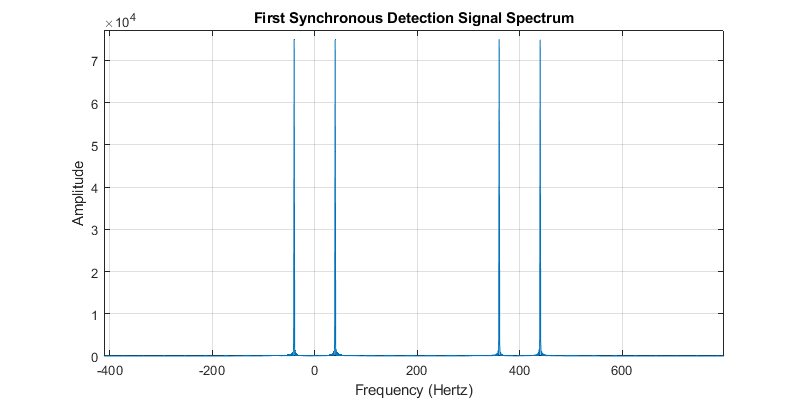


vamm1=ifftshift(ifft(vamf1));

multiplier1=cos(2*pi*fc1*t);
vam_m1= vamm1.*multiplier1; %Components : fc1-fm1, -fm1, fc1+fm1, fm1
vam_mf1= abs(fft(vam_m1));
f7=figure;
plot(kd,vam_mf1);
title("First Synchronous Detection Signal Spectrum");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f7,'Position',[0 0 800 400]);
grid on;

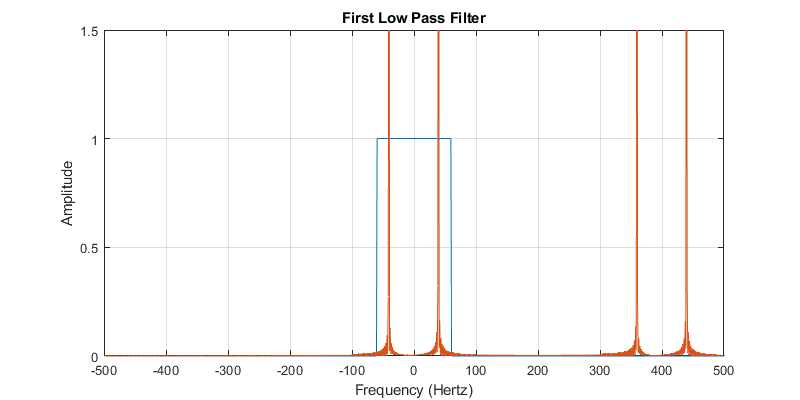


%lpf filter
tuner3=2*fm1+20;
lpf1=[zeros(1,a-tuner3),ones(1,2*tuner3),zeros(1,l-(a+tuner3))];

vmmf1=lpf1.*vam_mf1;
f7=figure;
plot(kd,lpf1);hold on
plot(kd,vam_mf1/10000);
title("First Low Pass Filter");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f7,'Position',[0 0 800 400]);
grid on;
xlim([-500 500])
ylim([0.000 1.500])


vmm1=ifft(ifftshift(vmmf1));
f7=figure;
plot(t,vmm1);hold on %modulated signal - blue

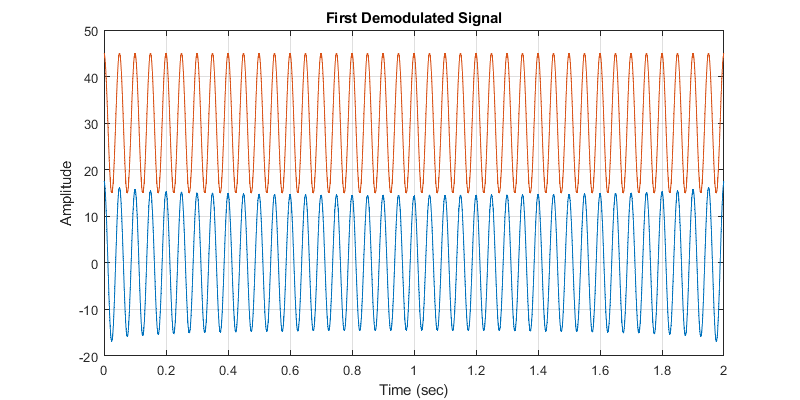

plot(t,3*vm1+30); %original signal - orange
title("First Demodulated Signal");
xlabel('Time (sec)');
ylabel('Amplitude');
set(f7,'Position',[0 0 800 400]);
grid on;

## For Second Signal :

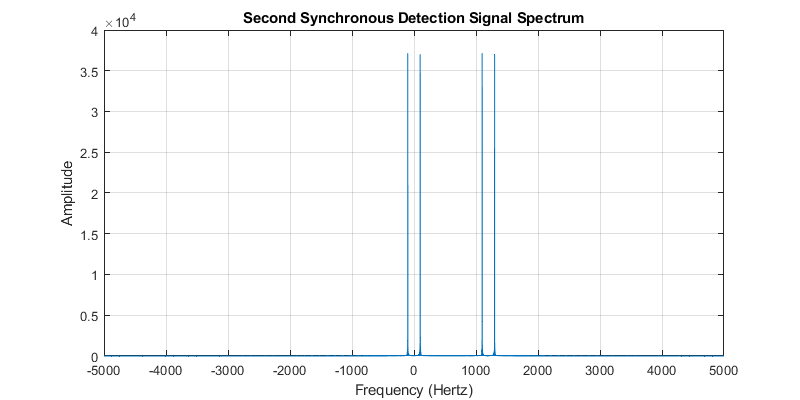

vamm2=ifftshift(ifft(vamf2));

multiplier2=cos(2*pi*fc2*t);
vam_m2= vamm2.*multiplier2; %Components : fc2-fm2, -fm2, fc2+fm2, fm2
vam_mf2= abs(fft(vam_m2));
f1=figure;
plot(kd,vam_mf2);
title("Second Synchronous Detection Signal Spectrum");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f1,'Position',[0 0 800 400]);
grid on;

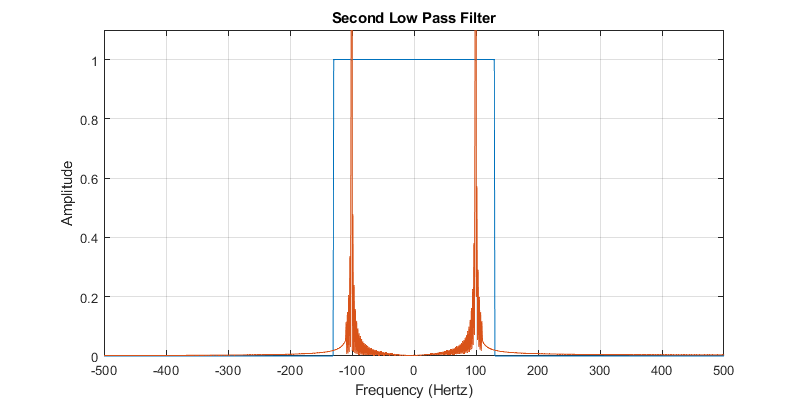


%lpf filter
tuner4=2*fm2+30;
lpf2=[zeros(1,a-tuner4),ones(1,2*tuner4),zeros(1,l-(a+tuner4))];

vmmf2=lpf2.*vam_mf2;
f5=figure;
plot(kd,lpf2);hold on
plot(kd,vam_mf2/4000);
title("Second Low Pass Filter");
xlabel('Frequency (Hertz)');
ylabel('Amplitude');
set(f5,'Position',[0 0 800 400]);
grid on;
xlim([-500 500])
ylim([0.000 1.100])


vmm2=ifft(ifftshift(vmmf2));
f6=figure;
plot(t,vmm2);hold on %modulated signal - blue

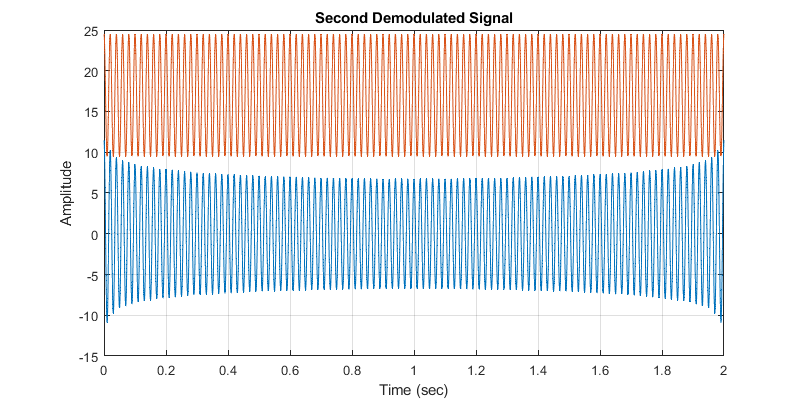

plot(t,2.5*vm2+17); %original signal - orange
% plot(t,3*vm1);
title("Second Demodulated Signal");
xlabel('Time (sec)');
ylabel('Amplitude');
set(f6,'Position',[0 0 800 400]);
grid on;